读取图片到工作空间，转化为双精度，并显示该图片

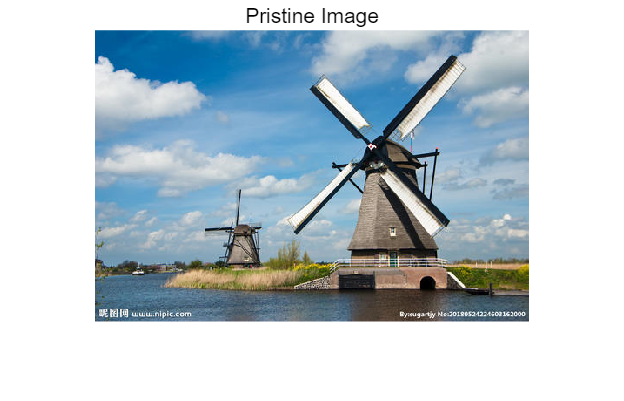

clc;
clear all;
close all;
pristineRGB = imread('picture0.jpg');
pristineRGB = im2double(pristineRGB);
figure("Name","1");
imshow(pristineRGB)
title('Pristine Image')

[pristineR,pristineG,pristineB] = imsplit(pristineRGB);

在图片上加入均值为0，方差为0.01的高斯白噪声，并显示加入噪声后的图片

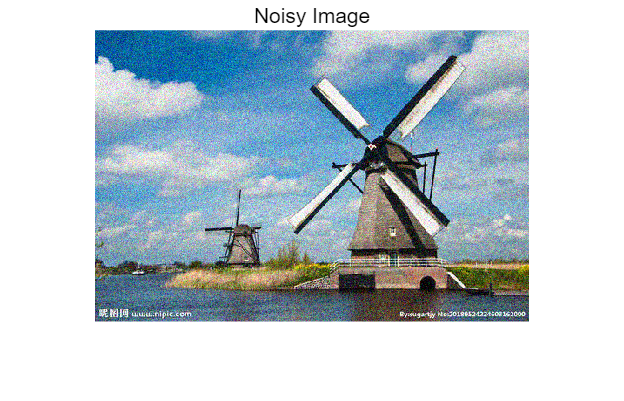

noisyRGB = imnoise(pristineRGB,'gaussian',0,0.01);%%高斯噪声
% noisyRGB = imnoise(pristineRGB,'poisson');%%泊松噪声
% noisyRGB = imnoise(pristineRGB,'salt & pepper');%%椒盐噪声
% noisyRGB = imnoise(pristineRGB,'speckle');%%乘性噪声
figure("Name","2");
imshow(noisyRGB)
title('Noisy Image')

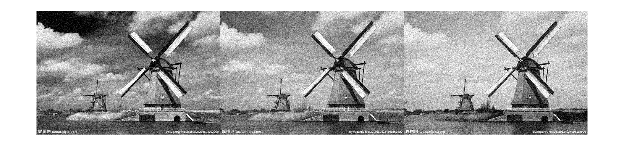

[noisyR,noisyG,noisyB] = imsplit(noisyRGB);
figure("Name","3");
montage({noisyR,noisyG,noisyB},'size',[1,3])

LMS降噪

M = 60;     %滤波器阶数M
% mu = 0.0008;  %滤波器的步长
mu=0.05;
[u,v,w]=size(pristineRGB);
N=u.*v;
k=2;%滤波器阶数
q=0.4;%步长
r=reshape(pristineR,N,1);%reshape按列依次排开
s=reshape(pristineG,N,1);
t=reshape(pristineB,N,1);
rr=reshape(noisyR,N,1);%含噪声的输入
ss=reshape(noisyG,N,1);
tt=reshape(noisyB,N,1);
%rrr=rr-r;
% sss=ss-s;
% ttt=tt-t;
rrr=0.01*randn(N,1);
sss=rrr;
ttt=sss;

卷积

N_window=3;%窗口长度
F_average=1/N_window*ones(1,N_window);%构建卷积核
i=0;
p=4;%卷积层数
lamda=0.2;

R

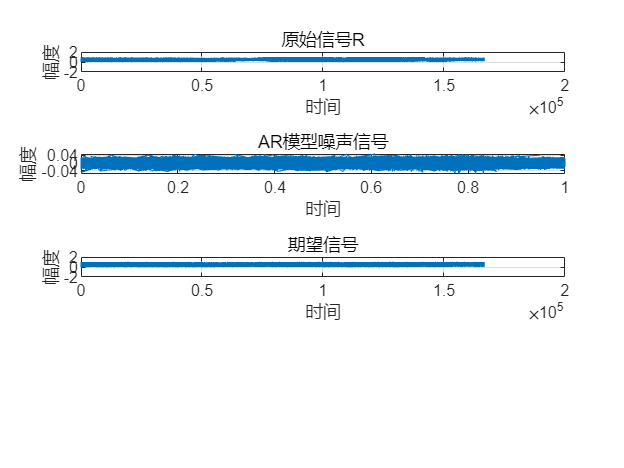

figure("Name","4");
subplot(4,1,1);
plot(1:N,r);grid;ylim([-2 2]);
ylabel('幅度');
xlabel('时间');
title('原始信号R');
%% 产生AR模型的噪声
arr=[1,1/2];   %AR模型
v_arr=filter(1,arr,rrr);
subplot(4,1,2);
plot(t,v_arr);grid;
ylabel('幅度');
xlabel('时间');
title('AR模型噪声信号');
 
%% 产生MA模型的噪声 是AR模型的相关噪声
% mar=[1,-0.8,0.4,-0.2];  %MA模型
% v_mar=filter(mar,1,rrr);
% subplot(4,1,2);
% plot(1:N,v_mar);grid;ylim([-2 2]);
% ylabel('幅度');
% xlabel('时间');
% title('相关噪声信号R');
 
%% 产生期望信号
dnr = rr + v_arr;
subplot(4,1,3);
plot(1:N,dnr);grid;ylim([-2 2]);
ylabel('幅度');
xlabel('时间');
title('期望信号');

## LMS滤波算法

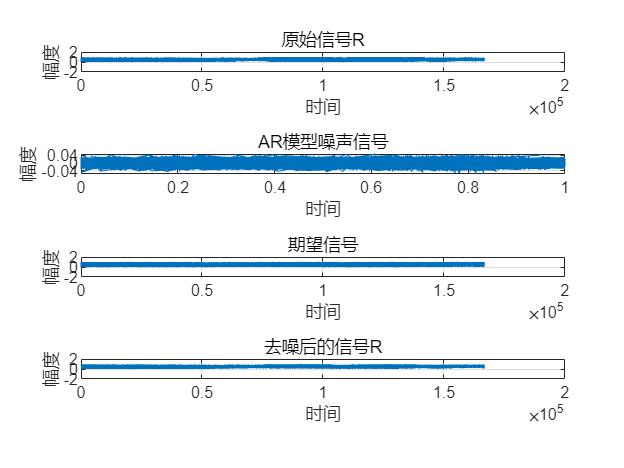

j=0;
while j<2
[ylmsr,W,elmsr] =LMSfilter(rr,dnr,M,mu);
[ylmsr1,W,elmsr1] =LMSfilter((fliplr(rr'))',(fliplr(dnr'))',M,mu); 
dnr=ylmsr;
j=j+1;
end
ylmsr=dnr;
%%卷积
while i<p
    yconr=conv(ylmsr,F_average,'same');
    yconr1=conv(ylmsr1,F_average,'same');
    i=i+1;
    ylmsr=yconr;
    ylmsr1=yconr1;
end
% yconr=conv(conv(ylmsr,F_average,'same'),F_average,'same');
% yconr1=conv(conv(ylmsr1,F_average,'same'),F_average,'same');
%%平滑处理
ysmor=smoothdata(yconr,'rloess',8);
ysmor1=smoothdata(yconr1,'rloess',8);
%% 绘制去噪后的信号
subplot(4,1,4);
plot(1:N,ylmsr);grid;ylim([-2 2]);
ylabel('幅度');
xlabel('时间');
title('去噪后的信号R');

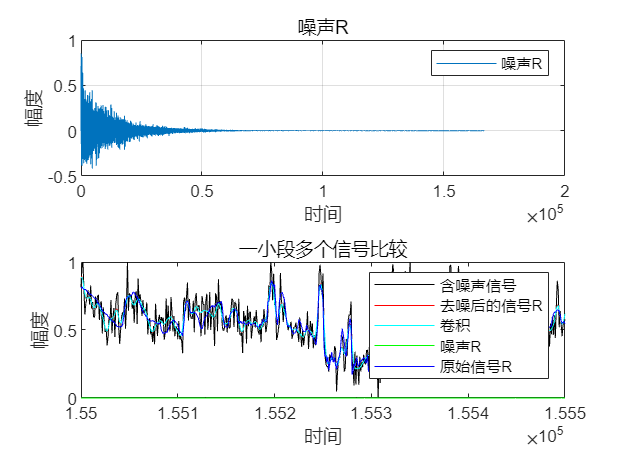

figure("Name","5");
subplot(2,1,1);
plot(1:N,elmsr);grid;
ylabel('幅度');
xlabel('时间');
title('噪声R');
legend('噪声R');
% 一小段三个信号比较
subplot(2,1,2);
time=(155000:155500);
plot(time,rr(155000:155500,1 ),'-k',time,ylmsr(155000:155500,1 ),'-r',time,ysmor(155000:155500,1 ),'-c',time,elmsr(155000:155500,1),'-g',time,r(155000:155500,1),'-b');
ylabel('幅度');
xlabel('时间');
legend('含噪声信号','去噪后的信号R','卷积','噪声R','原始信号R');
title('一小段多个信号比较');

G

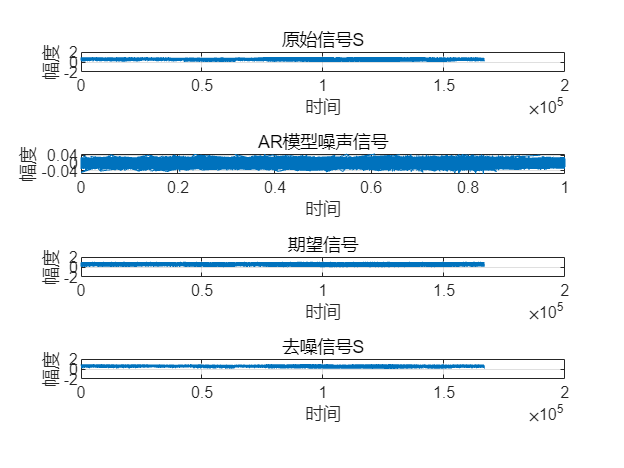

figure("Name","6");
subplot(4,1,1);
plot(1:N,s);grid;ylim([-2 2]);
ylabel('幅度');
xlabel('时间');
title('原始信号S');
%% 产生AR模型的噪声
ars=[1,1/2];   %AR模型
v_ars=filter(1,ars,sss);
subplot(4,1,2);
plot(t,v_ars);grid;
ylabel('幅度');
xlabel('时间');
title('AR模型噪声信号');
 
%% 产生MA模型的噪声 是AR模型的相关噪声
% mas=[1,-0.8,0.4,-0.2];  %MA模型
% v_mas=filter(mas,1,sss);
% subplot(4,1,2);
% plot(1:N,v_mas);grid;ylim([-2 2]);
% ylabel('幅度');
% xlabel('时间');
% title('相关噪声信号S');
 
%% 产生期望信号
dns = ss + v_ars;
subplot(4,1,3);
plot(1:N,dns);grid;ylim([-2 2]);
ylabel('幅度');
xlabel('时间');
title('期望信号');
 
%% LMS滤波算法
j=0;
while j<2
[ylmss,W,elmss] =LMSfilter(ss,dns,M,mu);
[ylmss1,W,elmss1] =LMSfilter((fliplr(ss'))',(fliplr(dns'))',M,mu);
dns=ylmss;
j=j+1;
end
ylmss=dns;
%%卷积
i=0;
while i<p
    ycons=conv(ylmss,F_average,'same');
    ycons1=conv(ylmss1,F_average,'same');
    i=i+1;
    ylmss=ycons;
    ylmss1=ycons1;
end
% ycons=conv(conv(ylmss,F_average,'same'),F_average,'same');
% ycons1=conv(conv(ylmss1,F_average,'same'),F_average,'same');
ysmos=smoothdata(ycons,'rloess',8);
ysmos1=smoothdata(ycons1,'rloess',8);
%% 绘制去噪后的语音信号
subplot(4,1,4);
plot(1:N,ylmss);grid;ylim([-2 2]);%平滑处理
ylabel('幅度');
xlabel('时间');
title('去噪信号S'); 

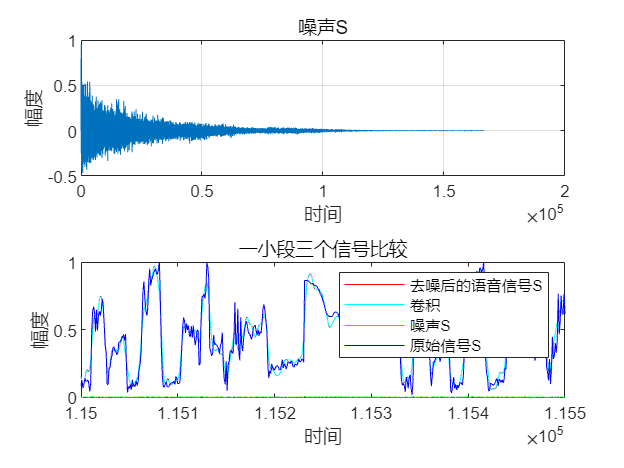

figure("Name","7");
subplot(2,1,1);
plot(1:N,elmss);grid;
ylabel('幅度');
xlabel('时间');
title('噪声S');
 
% 一小段三个信号比较
subplot(2,1,2);
time=(115000:115500);
plot(time,ylmss(115000:115500,1 ),'-r',time,ysmos(115000:115500,1 ),'-c',time,elmss(115000:115500,1),'-g',time,s(115000:115500,1),'-b');
ylabel('幅度');
xlabel('时间');
legend('去噪后的语音信号S','卷积','噪声S','原始信号S');
title('一小段三个信号比较');

B

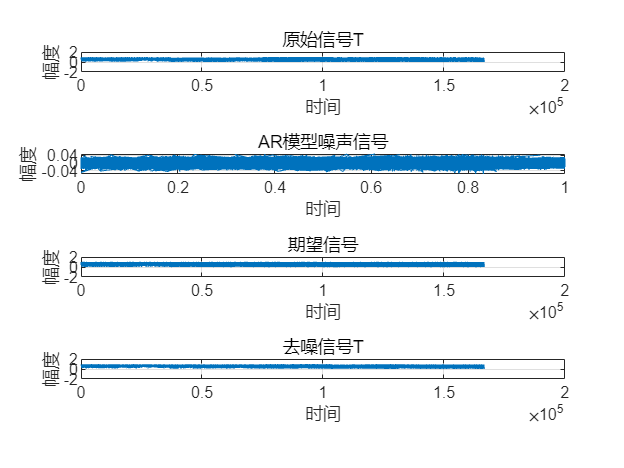

figure("Name","8");
subplot(4,1,1);
plot(1:N,t);grid;ylim([-2 2]);
ylabel('幅度');
xlabel('时间');
title('原始信号T');
%% 产生AR模型的噪声
art=[1,1/2];   %AR模型
v_art=filter(1,art,ttt);
subplot(4,1,2);
plot(t,v_art);grid;
ylabel('幅度');
xlabel('时间');
title('AR模型噪声信号');
 
%% 产生MA模型的噪声 是AR模型的相关噪声
% mat=[1,-0.8,0.4,-0.2];  %MA模型
% v_mat=filter(mat,1,ttt);
% subplot(4,1,2);
% plot(1:N,v_mat);grid;ylim([-2 2]);
% ylabel('幅度');
% xlabel('时间');
% title('相关噪声信号T');
 
%% 产生期望信号
dnt = tt + v_art;
subplot(4,1,3);
plot(1:N,dnt);grid;ylim([-2 2]);
ylabel('幅度');
xlabel('时间');
title('期望信号');
 
%% LMS滤波算法
j=0;
while j<2
[ylmst,W,elmst] =LMSfilter(tt,dnt,M,mu);
[ylmst1,W,elmst1] =LMSfilter((fliplr(tt'))',(fliplr(dnt')'),M,mu);
dnt=ylmst;
j=j+1;
end
ylmst=dnt;
%%卷积
i=0;
while i<p
    ycont=conv(ylmst,F_average,'same');
    ycont1=conv(ylmst1,F_average,'same');
    i=i+1;
    ylmst=ycont;
    ylmst1=ycont1;
end
% ycont=conv(conv(ylmst,F_average,'same'),F_average,'same');
% ycont1=conv(conv(ylmst1,F_average,'same'),F_average,'same');
ysmot=smoothdata(ycont,'rloess',8);
ysmot1=smoothdata(ycont1,'rloess',8);
%% 绘制去噪后的信号
subplot(4,1,4);
plot(1:N,ylmst);grid;ylim([-2 2]);
ylabel('幅度');
xlabel('时间');
title('去噪信号T');

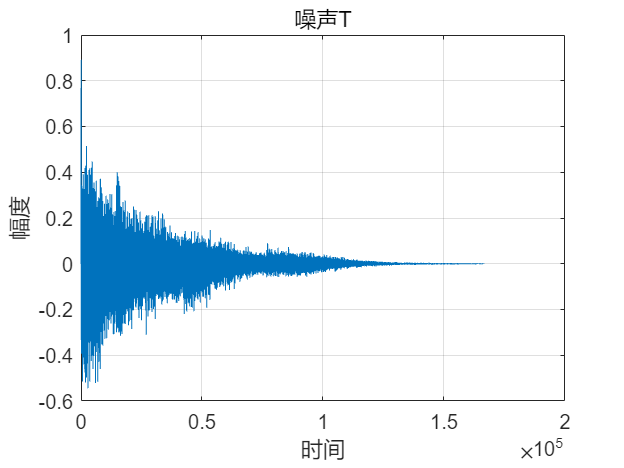

figure("Name","9");
plot(1:N,elmst);grid;
ylabel('幅度');
xlabel('时间');
title('噪声T');

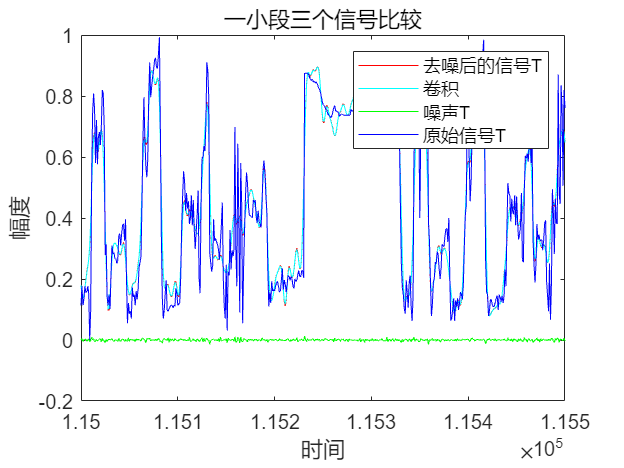

 
% 一小段三个信号比较
figure("Name","10");
time=(115000:115500);
plot(time,ylmst(115000:115500,1 ),'-r',time,ysmot(115000:115500,1 ),'-c',time,elmst(115000:115500,1),'-g',time,t(115000:115500,1),'-b');
ylabel('幅度');
xlabel('时间');
legend('去噪后的信号T','卷积','噪声T','原始信号T');
title('一小段三个信号比较');

降噪后图片

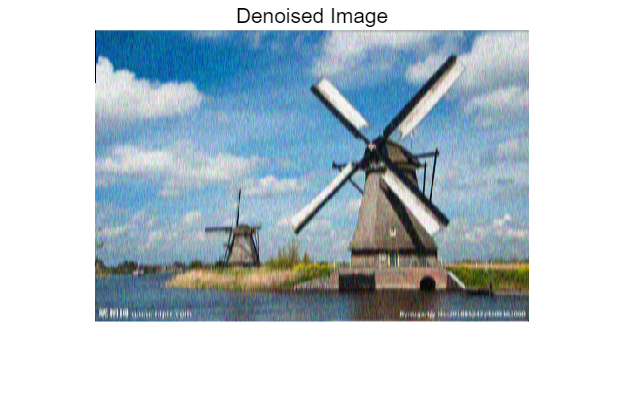

figure("Name","11");
denoisedR=reshape(ysmor,u,v);
denoisedS=reshape(ysmos,u,v);
denoisedT=reshape(ysmot,u,v);
denoisedRGB=cat(3,denoisedR,denoisedS,denoisedT);
imshow(denoisedRGB)
title('Denoised Image');

计算噪声图像和去噪图像的峰值信噪比(PSNR)。PSNR越大，说明噪声的相对信号越小，图像质量越高。

noisyPSNR = psnr(noisyRGB,pristineRGB);
fprintf('\n The PSNR value of the noisy image is %0.4f.',noisyPSNR);


 The PSNR value of the noisy image is 20.2002.

denoisedPSNR = psnr(denoisedRGB,pristineRGB);
fprintf('\n The PSNR value of the denoised image is %0.4f.',denoisedPSNR);


 The PSNR value of the denoised image is NaN.

计算去噪和去噪图像的结构相似度(SSIM)指数。SSIM指数接近1表示与参考图像吻合较好，图像质量较高。

noisySSIM = ssim(noisyRGB,pristineRGB);
fprintf('\n The SSIM value of the noisy image is %0.4f.',noisySSIM);


 The SSIM value of the noisy image is 0.6379.

denoisedSSIM = ssim(denoisedRGB,pristineRGB);
fprintf('\n The SSIM value of the denoised image is %0.4f.',denoisedSSIM);


 The SSIM value of the denoised image is NaN.

将原R分量前半段噪声截断，R分量颠倒顺序后，计算一次，同样截断前半段，从而降低信噪比。G,B分量亦如法炮制。

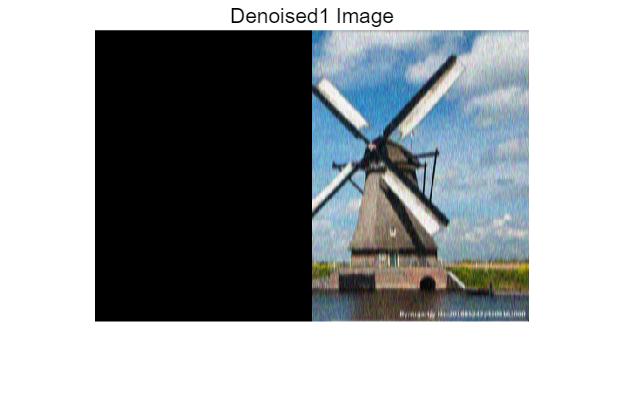

nu=round(N/2);
ylmsr11=[fliplr(ysmor1(nu:end,1)'),ysmor(nu+2:end,1)']';
ylmss11=[fliplr(ysmos1(nu:end,1)'),ysmos(nu+2:end,1)']';
ylmst11=[fliplr(ysmot1(nu:end,1)'),ysmot(nu+2:end,1)']';
denoisedR1=reshape(ylmsr11,u,v);
denoisedS1=reshape(ylmss11,u,v);
denoisedT1=reshape(ylmst11,u,v);
denoisedRGB1=cat(3,denoisedR1,denoisedS1,denoisedT1);
figure("Name","12")
imshow(denoisedRGB1)
title('Denoised1 Image');

denoisedPSNR1 = psnr(denoisedRGB1,pristineRGB);
fprintf('\n The PSNR value of the denoised image is %0.4f.',denoisedPSNR1);


 The PSNR value of the denoised image is NaN.

denoisedSSIM1 = ssim(denoisedRGB1,pristineRGB);
fprintf('\n The SSIM value of the denoised image is %0.4f.',denoisedSSIM1);


 The SSIM value of the denoised image is NaN.